# Control of Electric Drives and Power Converters

## Assignment 1.

#### Tasks 1 & 2.

Determining the number of pole pairs:

n = 1436; % Nominal motor speed [rpm]
f = 50; % Frequency [Hz]
n_p = floor(60*f/n);

From the calculation we can see that


$$n_p =\frac{60*50\;\textrm{Hz}}{1436\;\frac{r}{\min }}=2$$


For the first task of the assignment, we were asked to derive the equations for the stator current $i_s^s$ and the rotor current $i_R^s$ as a function of stator flux $\psi_s^s$ and rotor flux $\psi_R^s$ in stator coordinates. This was achieved by inserting gain and summation blocks in the "Flux equations" function bloc, as seen in the Fig. 1

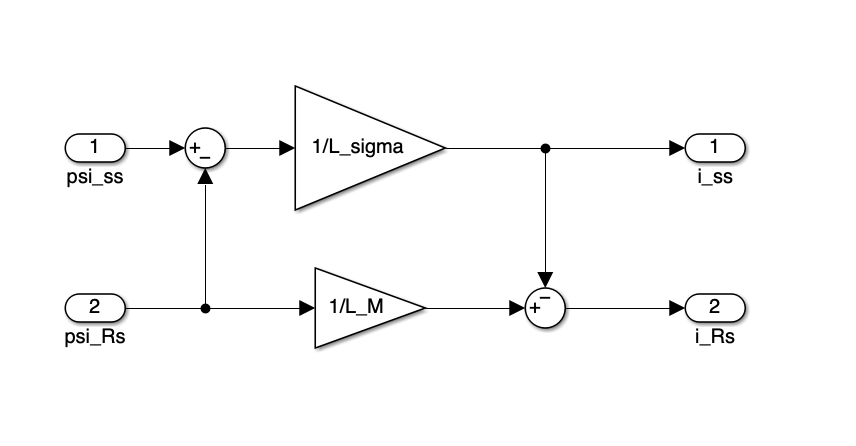 

*Figure 1. Flux equations fuction block*

After this, the equation for electromagnetic torque was formed inside the "Electromagnetic torque" function block, as seen in the Fig. 2.

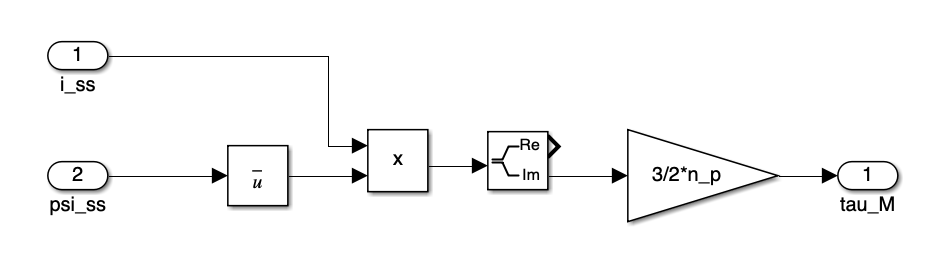

*Figure 2. Electromagnetic torque control block*

The nominal torque $\tau_N =\frac{P_N }{\omega_N }=\frac{P_N }{n_N \frac{2\pi }{60s}}=\frac{2200W}{1436\frac{1}{\min }\frac{2\pi }{60s}}\approx 14\ldotp 63\textrm{Nm}$

The nominal peak to peak line to neutral voltage $v_{p-p,\textrm{pn}} =\sqrt{2}\;\frac{\;400V}{\sqrt{3}}\approx 326\ldotp 6V$

#### Task 3.

The missing part of the algorithm was completed by inserting the equation for $u_s^s$, which is


$$u_s^s \left(k\right)=\psi_{s,\textrm{ref}} *\omega_{s,\textrm{ref}} \left(k\right)*e^{j\theta_s \left(k\right)\;\;}$$


Running the intialization script:

init_vhz;

Simulating the system:

sim("vhz.slx");

Plotting the result:

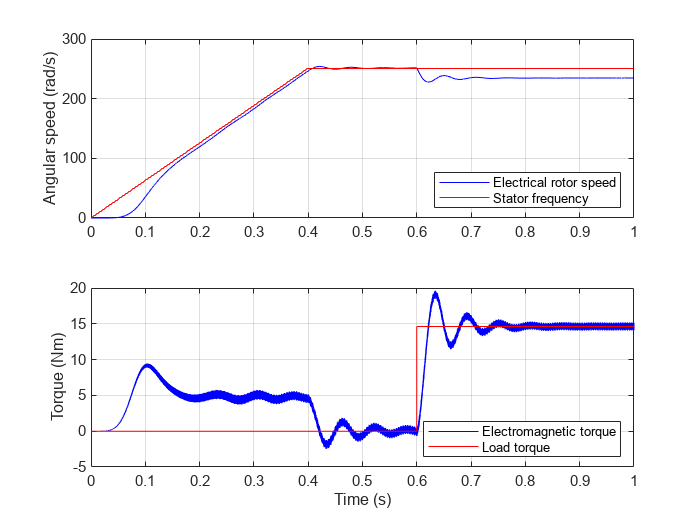

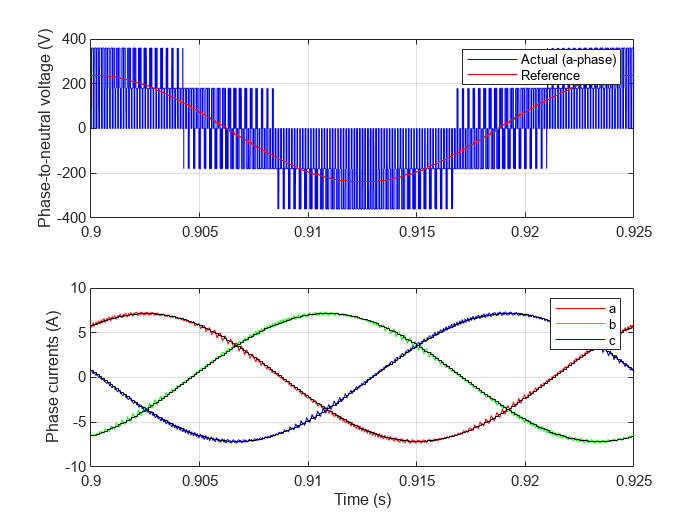

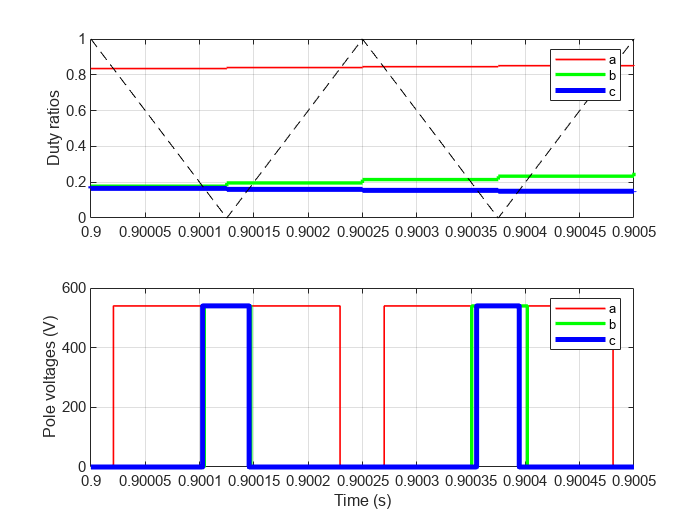

fig_vhz;

The figures seem to match pretty well with the one's given in the assignment for comparison.

#### Task 4.

The stator voltage for these calculations was approximated by using the equation


$$u_s =\omega_{s,\textrm{ref}} \psi_{s,\textrm{ref}} =2\pi 40\;\frac{\textrm{rad}}{s}*0\ldotp 95\;\textrm{Vs}=238\ldotp 76\;V$$


The stator impedance in steady state is


$$Z_s =R_s +j\omega \left(L_{\sigma } +L_M \right)=3\ldotp 7\Omega +\textrm{j80}\pi \frac{\textrm{rad}}{s}\;\left(21\;\textrm{mH}+224\;\textrm{mH}\right)=\left(3\ldotp 7+\textrm{j61}\ldotp 57\right)\Omega$$


And hence, the peak stator current is


$$i_s =\frac{u_s }{{|Z}_s |}=3\ldotp 87\;A$$


Plotting the calculated stator current value against the simulated one can be seen in Fig. 3. For the simulation, the load torque step final value was set to 0, but the rate limiter of the speed reference was kept untouched, which explains the peaks in stator current before reaching steady state.

T_L = 0; % load torque
sim("vhz.slx");
task_4_script;

*Figure 3. Simulated and calculated stator current*

As can be seen from the figure the calculated stator current value matches the simulated one quite well in steady state operating area. Losses due to the stator resistance were omitted in the controller u_ref calculation, and therefore the voltage drop due to the resistance is omitted here as well.

#### Task 5.

To decrease $f_{\textrm{sw}}$ to 2kHz we calculated sampling period $T_S$ to correspond to the lower switching frequency.

init_vhz;
f_sw = 2e3; % switching frequency
T_s = 1/(2*f_sw); % sampling period
T_L = 14.63; % returning the load torque back to its nominal value

Simulating the model again with new parameters and running the plotting script.

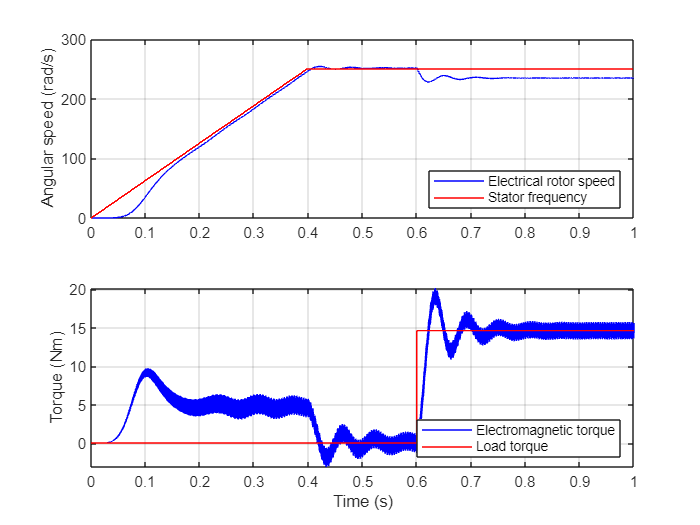

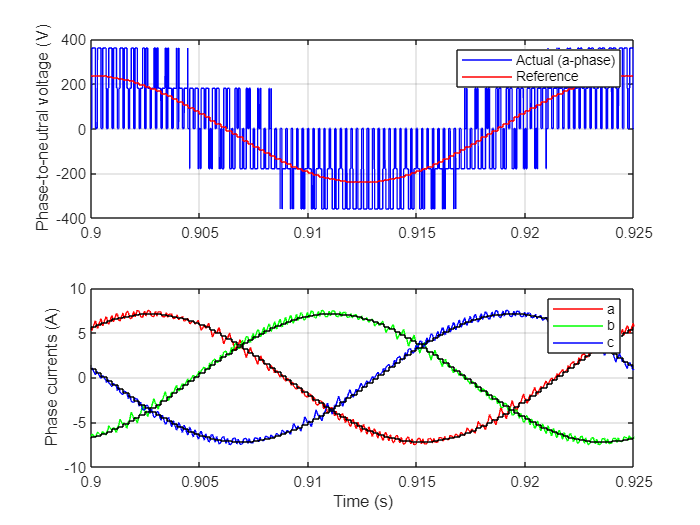

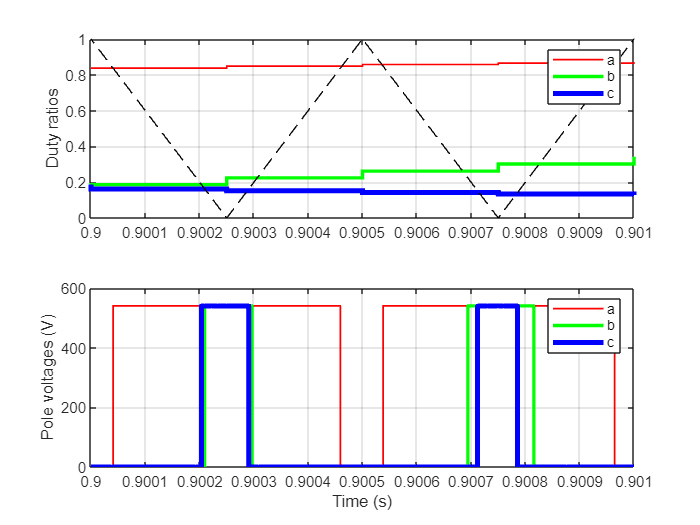

sim("vhz.slx");
fig_vhz;

Decreasing the switching frequency seems to increase the harmonic content in the phase currents, which leads to the harmonic content increasing in the electromagnetic torque as well, ie. torque ripple. The response of the system (overshoots, response time) remains the same, because the current remains the same effectively. While decreasing the switching frequency, the efficiency of the converter increases due to reduced switching losses, the torque ripple is not desired behaviour in some applications.

#### Task 6.

The transformation from abc to dq was done by implementing the transformation equations

$i_s^s =\frac{2}{3}\left(i_a {+i}_b e^{\textrm{j2}\frac{\pi }{3}\;} +i_c e^{\textrm{j4}\frac{\pi }{3}\;} \right)$, which is the transformation from abc to $\alpha$$\beta$-coordinate space vector, and

$i_s =i_s^s e^{-j{\hat{\vartheta \;} }_s \;}$, which is the transformation from  $\alpha$$\beta$-coordinates to dq-coordinates

inside the abc2dq function block in vector control subsystem. The implementation was done in following manner: (code is commented, because the report is done in MATLAB Live Editor, and the code blocks are run when forming the document). 

% Space-vector transformation and coordinate transformation
%i_ss = 2/3*(i_a+i_b*exp(1i*2*pi/3)+i_c*exp(1i*4*pi/3)); % abc to alfa-beeta
%i_s = i_ss*exp(-1i*theta_s); 	% alfa-beeta to dq

#### Task 7.

The calculations for $i_{d,\textrm{ref}}$ and $i_{q,\textrm{ref}}$ were added by using the equations

$i_{d,\textrm{ref}} =\frac{\psi_{R,\textrm{ref}} }{\hat{L_M \;} }\;$and


$$i_{q,\textrm{ref}} =\frac{2\tau_{M,\textrm{ref}} }{3n_p \psi_{R,\textrm{ref}} \;}\;$$


Algorithm was implemented as follows (again commented here to avoid problems):

% Current reference in estimated rotor-flux coordinates
% i_d_ref = psi_R_ref/L_M;
% i_q_ref = 2*tau_M_ref/(3*n_p*psi_R_ref);

#### Task 8.

The angular frequency of the rotor flux is estimated using the equation


$$\hat{\;\omega_s \;} =\omega_m +\hat{\;\frac{R_R i_q }{\hat{\;\psi_R \;} }}$$


The magnitude of the rotor flux is estimated using the equation

$\frac{d\psi_R }{\textrm{dt}}=\hat{R_R \;} \left(i_d -\hat{\frac{\psi_R }{\hat{L_M \;} }} \right)$, for which the corresponding forward Euler approximation is


$$\psi_R \left(k+1\right)=\psi_R \left(k\right)+T_s \left(-\frac{R_R }{L_M }\psi_R \left(k\right)+R_R i_d \right)$$


Algorithm was implemented as follows

%if(psi_R > 0) 	                    % Avoid division by zero
%	w_s = w_m+R_R*i_q/psi_R;
%else
%	w_s = w_m;
%end

% Update the states
%psi_R_new = psi_R+T_s*((-R_R/L_M)*psi_R+R_R*i_d);

#### Task 9.

Running the initialization script:

init_vector;

Simulating the model:

sim("vector_model.slx");

Plotting the result:

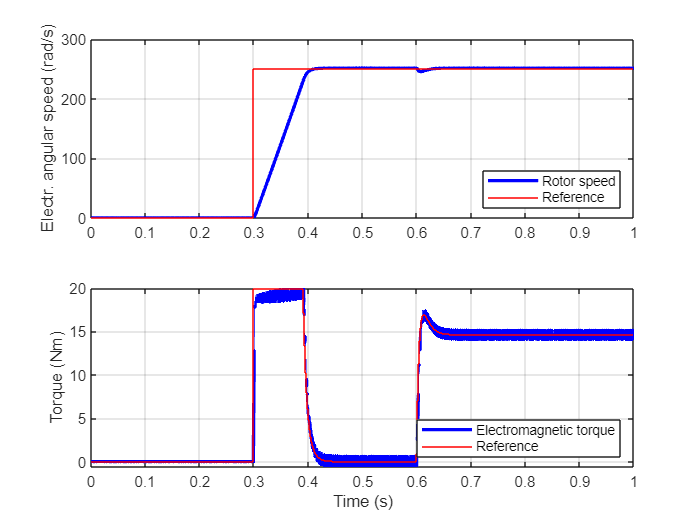

speed_torque;

The results seem to match those presented in the Fig. 11 of the assignment instructions figure, so the model seems to work fine.

#### Task 10.

To calculate $i_d$, $i_q$ and $|\mathbf{i_{s}}|$ we use following equations.


$$i_d =\frac{\psi_R }{L_M }$$



$$i_q =\frac{2\tau_M }{3n_p \psi_R }$$



$${\mathit{\mathbf{i}}}_{\mathit{\mathbf{s}}} =i_d +{\textrm{ji}}_q$$


where $\tau_M$=14.63Nm, $n_p=2$, $\psi_R=0.9Vs$ and $L_M=224mH$

For $u_d$, $u_q$ and $|\mathbf{u_s}|$ we use equations: 


$$\begin{array}{l}
\omega_m =n_p \omega_M \\
T_r =\frac{L_M }{R_R }\\
\tau_M =\frac{3n_p }{2}\textrm{Im}\left\lbrace \frac{j\omega_r \psi_{\mathit{\mathbf{R}}} }{R_R }{\psi_{\mathit{\mathbf{R}}}^* } \right\rbrace =\frac{3n_p }{2}\frac{\psi_R^2 }{R_R }\omega_r \\
\omega_r =\frac{2\tau_M }{3n_p }\frac{R_R }{{\psi^2 }_R }\\
{\mathit{\mathbf{i}}}_{\mathit{\mathbf{s}}} =\frac{\psi_{\mathit{\mathbf{s}}} }{L_{\sigma } +\frac{L_M }{1+j\omega_r T_r }}\\
\psi_{\mathit{\mathbf{s}}} ={\mathit{\mathbf{i}}}_{\mathit{\mathbf{s}}} \left(L_{\sigma } +\frac{L_M }{1+j\omega_r T_r }\right)\\
\omega_s =\omega_r +\omega_m 
\end{array}$$



$$\begin{array}{l}
{\mathit{\mathbf{u}}}_{\mathit{\mathbf{s}}} =R_s {\mathit{\mathbf{i}}}_{\mathit{\mathbf{s}}} +j\omega_s \psi_{\mathit{\mathbf{s}}} \\
u_d =\textrm{Re}\left\lbrace {\mathit{\mathbf{u}}}_{\mathit{\mathbf{s}}} \right\rbrace \\
u_q =\textrm{Im}\left\lbrace {\mathit{\mathbf{u}}}_{\mathit{\mathbf{s}}} \right\rbrace 
\end{array}$$


Calculating the values using the above equations with a script:

task10;

i_d = 4.0179

i_q = 5.4185

i_s_abs = 6.7456

u_d_calc = -15.1709

u_q_calc = 279.8946

u_s_abs = 280.3054

The results can be seen above. In comparison to the simulated values, the calculated ones match well once the system has reached steady state. Comparison can be seen in the following figures.

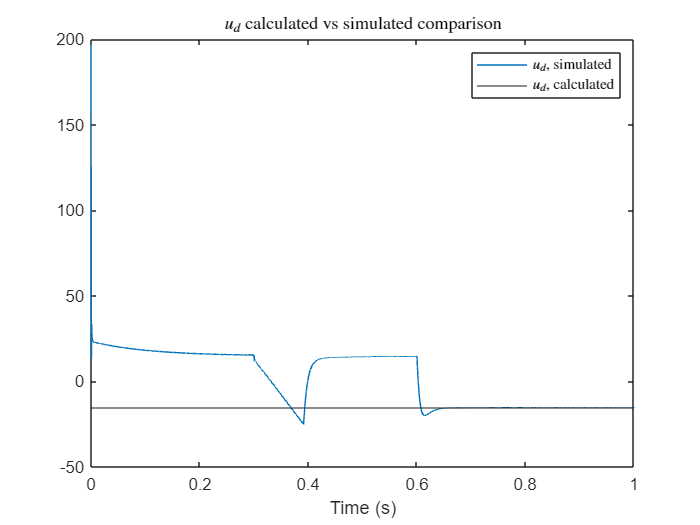

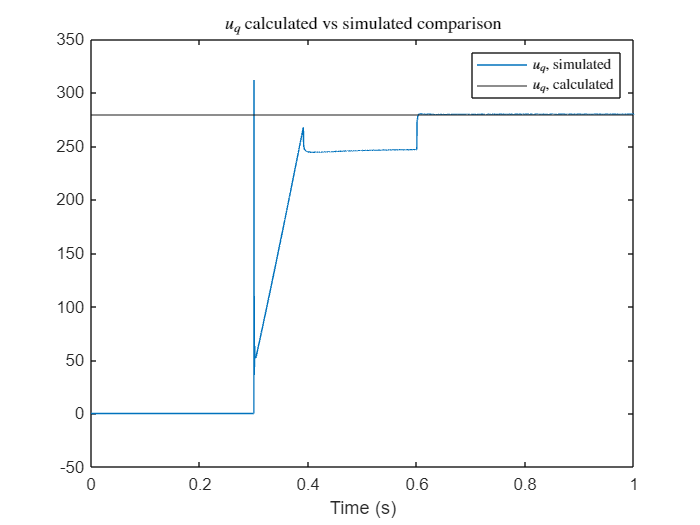

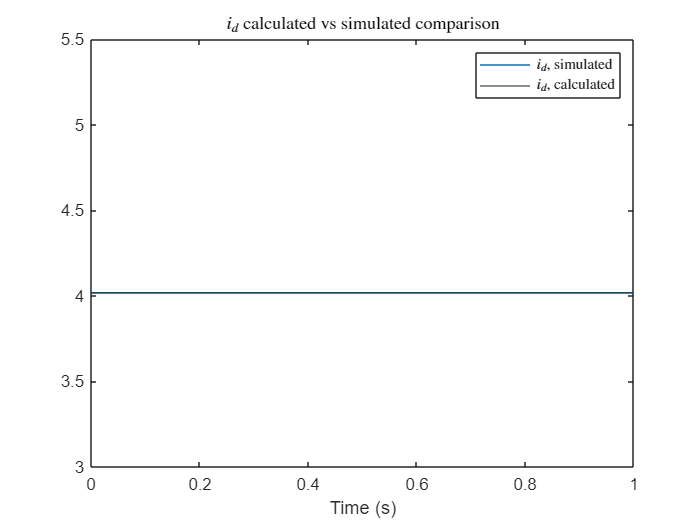

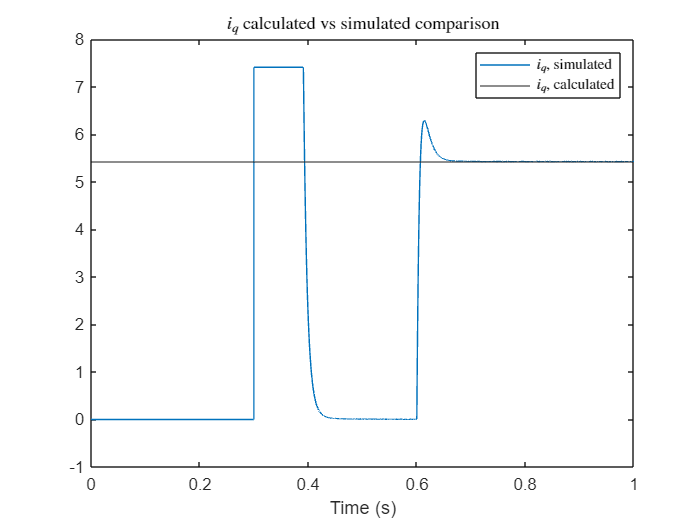

task_10_script;

#### Task 11.

For this task, we initialize a new variable $R_{R,\mathrm{actual}}$ and set it for the rotor resistance in the induction motor simulation model mask. This way we can alter this value, without the value inside the control system changing.

 Simulation with 120 % rotor resistance value:

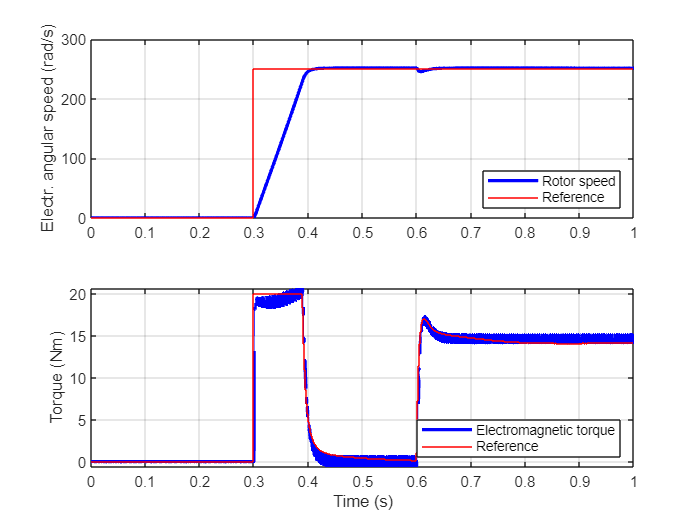

R_R_actual = 1.2*R_R;
sim("vector_model.slx");
speed_torque;

Simulation with 150 % rotor resistance:

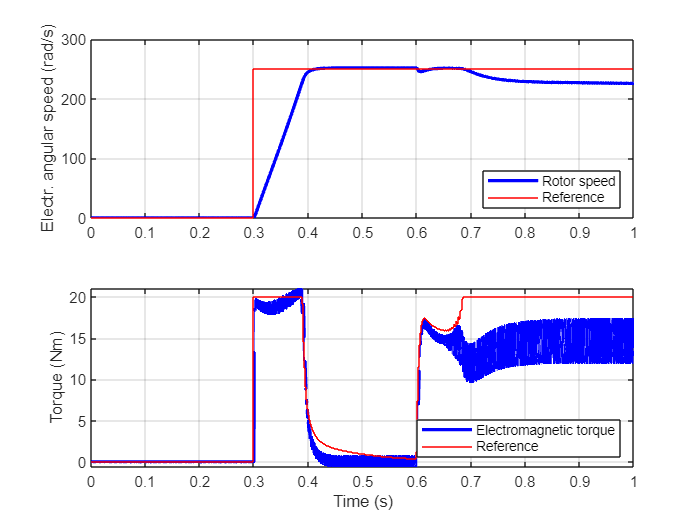

R_R_actual=R_R*1.5;
sim("vector_model.slx");
speed_torque;

The system seems to withstand 120 % rotor resistance quite well, but with 150 % value the torque ripple and the offset to reference in steady state increaces noticeably. This is due to the flux estimation being incorrect, which directly affects the torque reference. 

Setting the value back to nominal: 

R_R_actual = R_R;

#### Task 12.